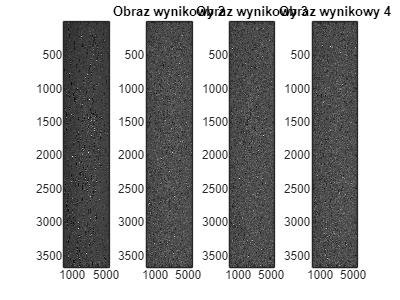

data=load('C:\Users\milka\Desktop\MGR\Holograms\Bio\HPB\USAF-1.mat');
img_HPB=double(data.u);
img_HPB=img_HPB/mean2(img_HPB);
[img_result,img_noise]=process_images(img_HPB,2,3);
[rows,cols,~]=size(img_HPB); 
       

% for ii=1:length(img_result)
%     mp=mean2(img_result{ii})
%     mn=mean2(img_noise{ii})
% end

figure()
for ii=1:length(img_result)+1
    subplot(1,length(img_result)+1,ii)
    title(sprintf("Obraz HPB"))
    if ii==1
    imagesc(img_HPB); colormap gray;
    else
    imagesc(img_result{ii-1}); colormap gray;
    title(sprintf("Obraz wynikowy %i",ii))
    end
end